## **Forward TRF example**

This is an example of a forward TRF scenario in the case of a food diary dataset. The objective is to determine possible food intolerances. This example dataset is synthesised.

X is a CND structure containing the food diary. 365 entries (one per day within a year). Each entry contains binary values indicating if the individual ate a particular type of food on a given day. Rows indicate days. Columns indicate the following food sources:  'gluten','milk','legumes','sulfites','nightshades','egg','fish','caffeine','ground pepper','alcohol','carrot'

y is a CND structure containing subjective reportings of stomachache, with 5 possible values from 'no pain' to 'very painful' (0, 0.25, 0.5, 0.75, 1). 

This live script starts by generating the example data. Then it runs the mTRF.

Author: Giovanni M. Di Liberto (https://www.diliberg.net/)

Please cite:

- mTRF-Toolbok: [https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full](https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full) 

- Open science framework: [https://arxiv.org/abs/2309.07671](https://arxiv.org/abs/2309.07671) 

Please check out

- mTRF-Toolbox - Considerations for applied research: [https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full](https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full) 

- CND dataset available here: [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html) 

### Workspace setup

This section clears the workspace and adds the library folders to the Matlab paths

clear all
close all

addpath ./examples/libs/cnsp_utils
addpath ./examples/libs/cnsp_utils/cnd
addpath ./mtrf
addpath ./examples/libs/filedownload

### Data preparation

This section creates the sample data (see explanation above). Note that X is what is usually the 'stim' of the mTRF (uppercase 'X', as it contains a matrix). y is what is usually the neural data (lowercase 'y', as it contains a vector). 

% Hyperparameters
datasetName = "foodDiary";
nDays = 365; % How many days in the dataset
% nDays = 365*10; % Let's try with more data!

% CND strucure hyperparameters
X.names{1} = 'Food diary (binary features)'; % The '{1}' refers to the first set of features (e.g., usually 'envelope', 'word onset'). Here we only need one i.e., the multivariate food diary
X.colNames{1} = {'gluten','milk','legumes','sulfites','nightshades', ...
                'egg','fish','caffeine','ground pepper','alcohol','carrot'};
X.fs = 1; % this is generally in Hz. Just for this example, we set it to 1, meaning 1 sample per day
X.stimIdxs = 1; % We generally have many 'runs' or 'trials', which are then used for cross-validation. 
                % We just need one 'trial' in this example
% Food diary data
X.data{1} = double(rand(nDays,length(X.colNames{1}))>0.5); % 50% chance of having a 0 vs. a 1. As many columns as food types

We have created our food diary. Let's have a look at 'gluten'.

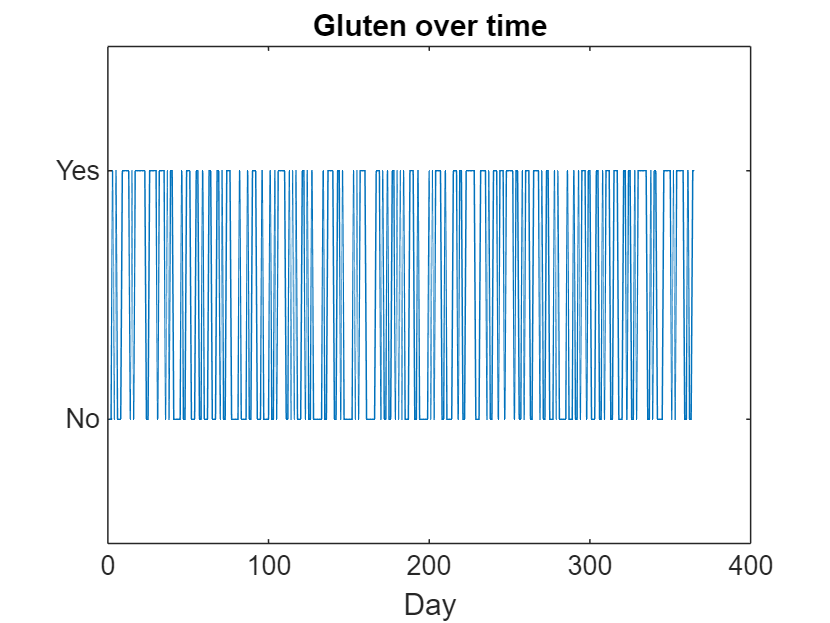

figure; plot(X.data{1}(:,1)); xlabel('Day'); ylim([-0.5,1.5]); yticks([0,1]); yticklabels({'No','Yes'}); title('Gluten over time');

Let's generate the subjective reporting of stomachache 'y'.

y.fs = 1; % same as for X
y.dataType = 'Stomachache';
y.deviceName = 'Subjective reporting (1-5; 1: no, 2: little, 3: medium, 4: bad, 5: very bad)';
y.data{1} = zeros(nDays,1); % zero vector

% Let's create data for an individual with gluten and milk intolerance
% Gluten is in column 1. Milk in colum 2
% Let's say that gluten has a delayed and prolonged reaction
% and that milk has a reaction on the same day
% Note that these are just numerical examples, which are completely made up.
% They don't reflect actual gluten and milk intolerances.
glutenIdxs = find(X.data{1}(:,1));
milkIdxs   = find(X.data{1}(:,2));
for ii = glutenIdxs'
    if ii+1 <= length(y.data{1})
        y.data{1}(ii+1) = y.data{1}(ii+1) + 0.75; % bad after 1 day
    end
    if ii+2 <= length(y.data{1})
        y.data{1}(ii+2) = y.data{1}(ii+2) + 0.25; % medium after 2 days
    end
    if ii+3 <= length(y.data{1})
        y.data{1}(ii+3) = y.data{1}(ii+3) + 0.25; % mild after 3 days
    end
    if ii+4 <= length(y.data{1})
        y.data{1}(ii+4) = y.data{1}(ii+4) + 0.25; % mild after 3 days
    end
end
for ii = milkIdxs'
    if ii <= length(y.data{1})
        y.data{1}(ii) = y.data{1}(ii) + 0.50; % medium on the same day
    end
end
% Cap stomachache to max value 1
y.data{1}(y.data{1}>1) = 1;


Let's have a look at 'y':

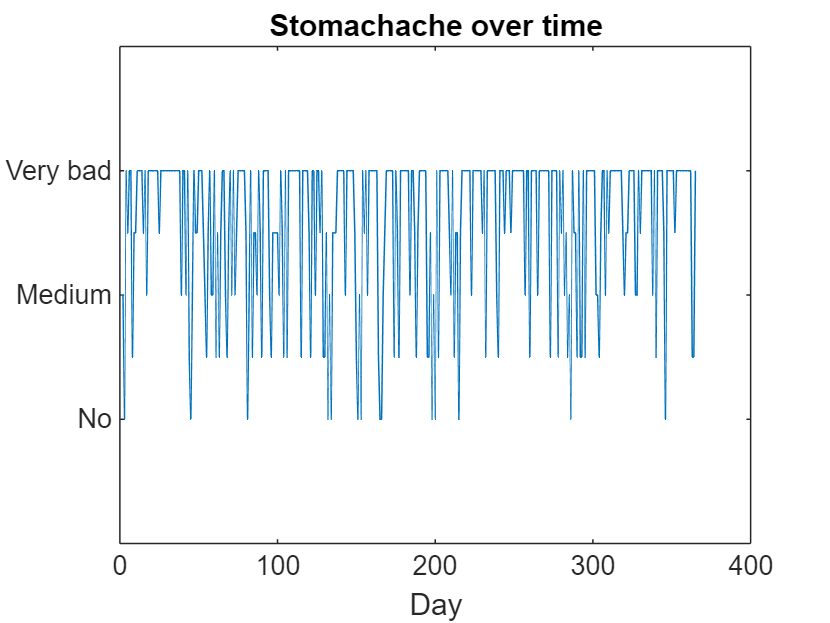

figure; plot(y.data{1}); xlabel('Day'); ylim([-0.5,1.5]); title('Stomachache over time');
yticks([0,0.5,1]); yticklabels({'No','Medium','Very bad'}); 

### Forward mTRF model fit

Setting up mTRF hyperparameters

tmin = -7

tmin = -7

tmax = 13

tmax = 13

lambdas = 10.^(-4:2:4); % small set of lambdas
dirTRF = 1; % Forward TRF model
stimIdx = 1; 


Forward TRF (unregularised)

disp('Running mTRFtrain')

Running mTRFtrain


model = mTRFtrain(X.data(stimIdx,:),y.data,y.fs*1000,dirTRF,tmin,tmax,0,'verbose',0);    

Let's plot the mTRF weights for different features

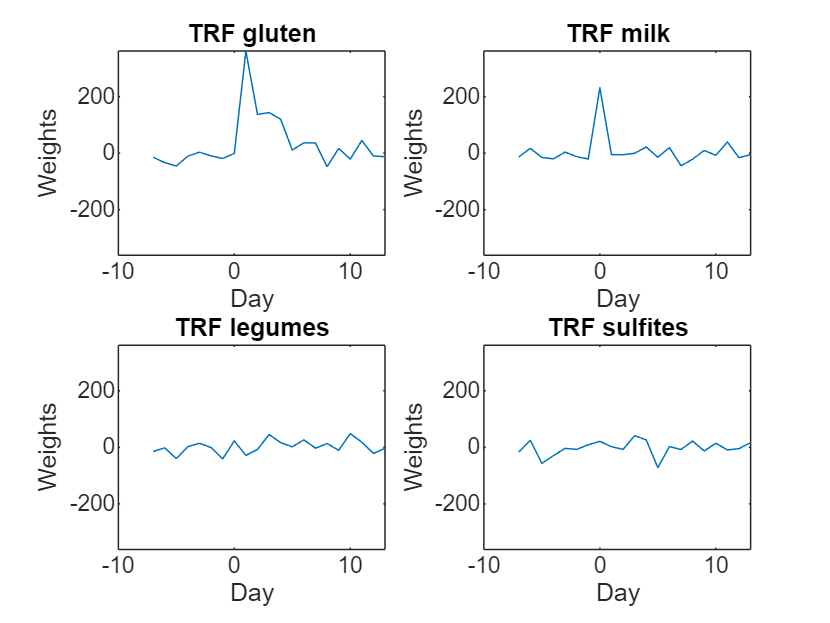

maxVal = max(abs(model.w(:)));

figure;
for iiFea = 1:4
    subplot(2,2,iiFea)
    plot(model.t,model.w(iiFea,:))
    ylim([-maxVal,maxVal])
    xlabel('Day')
    ylabel('Weights')
    title("TRF "+X.colNames{1}{iiFea})
end

Let's look at this from a different angle

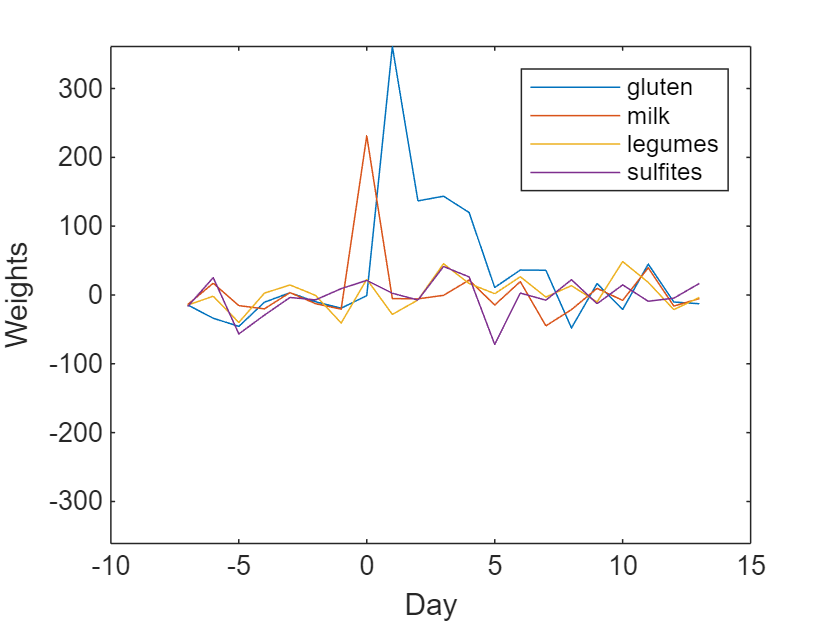

figure;
for iiFea = 1:4
    plot(model.t,model.w(iiFea,:))
    hold on
end
maxVal = max(abs(model.w(:)));
ylim([-maxVal,maxVal])
xlabel('Day')
ylabel('Weights')
legend(X.colNames{1}(1:4))